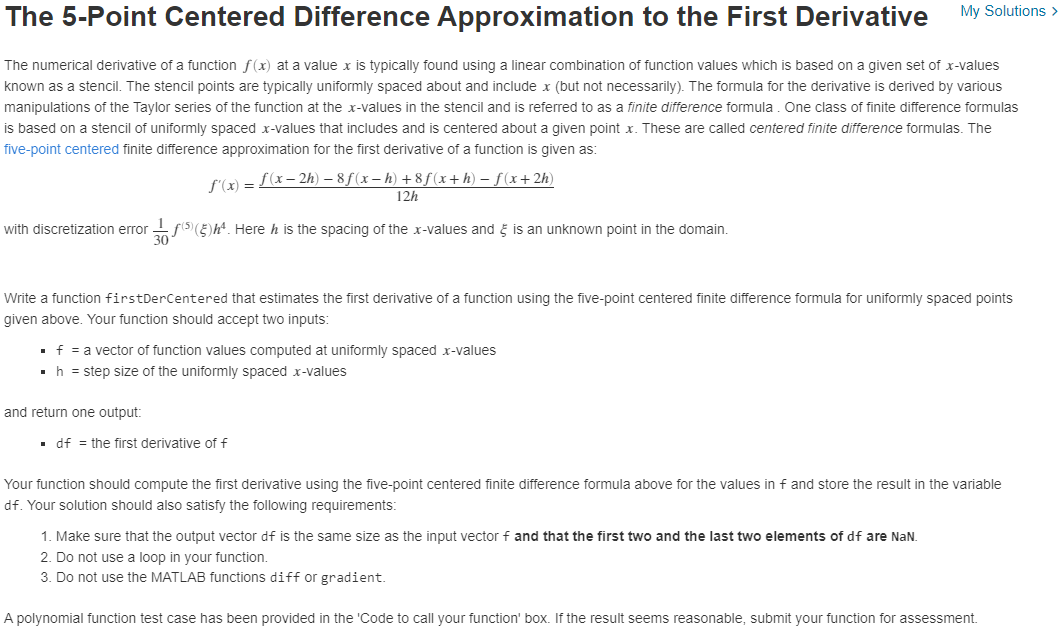


h = 0.1;
x = 0:h:0.7;
f = 1 + x + x.^4;
df = firstDerCentered(f,h)

df =        NaN       NaN    1.0320    1.1080    1.2560    1.5000       NaN       NaN


function  df = firstDerCentered(f,h)

    % Compute the 5 point centered finite difference vector df.
    % Make sure the first and last two values of df are NaN.
    l=length(f);
    if l < 5
        error("El vector df es:",nan(size(f)));
    end
    x1=f(1:l-4); %x-2h 
    x2=f(2:l-3); %x-h
    x3=f(4:l-1);%x+h
    x4=f(5:l);%x+2h
    df = nan(size(f));
    df(3:l-2)= (x1-(8*x2)+(8*x3)-x4)/(12*h);
    
end